## Operational amplifier circuits

### 1. Simple inverting op-amp

The ideal operational amplifier is supported as a 3-terminal element. Let's see how the program handles circuits with OpAmps included. The analysis is done as with any other circuit.

circuit = Circuit('circuits/r_op_amp.txt');
circuit.list

ans =     'Vs 1 0 AC Vs
     R1 1 2 R1
     R2 2 3 R2
     O1 0 2 3
     '


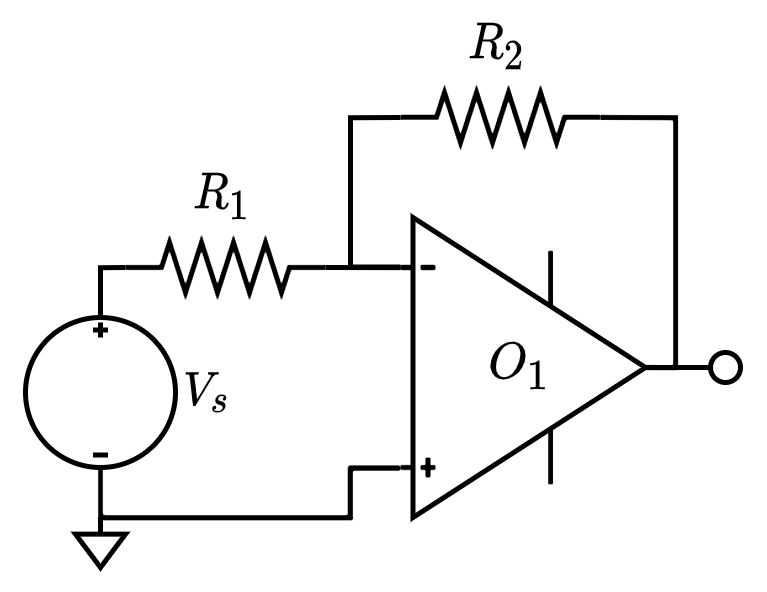

ELAB.analyze(circuit)

Symbolic analysis successful (0.243211 sec).


circuit.symbolic_node_voltages

$$ans = \left(\begin{array}{c} v_{1}=\mathrm{Vs}\\ v_{2}=0\\ v_{3}=-\frac{R_{2}\,\mathrm{Vs}}{R_{1}} \end{array}\right)$$

### 2. Inverting op-amp with additional reactive elements.

This is a slightly more complex example. We are still dealing with an inverting amplifier configuration.

circuit = Circuit('circuits/rc_op_amp.txt');
circuit.list

ans =     'Vs 1 0 AC Vs
     R1 1 2 20000
     R2 3 4 20000
     C1 2 3 C1
     C2 3 4 C2
     O1 0 3 4
     '


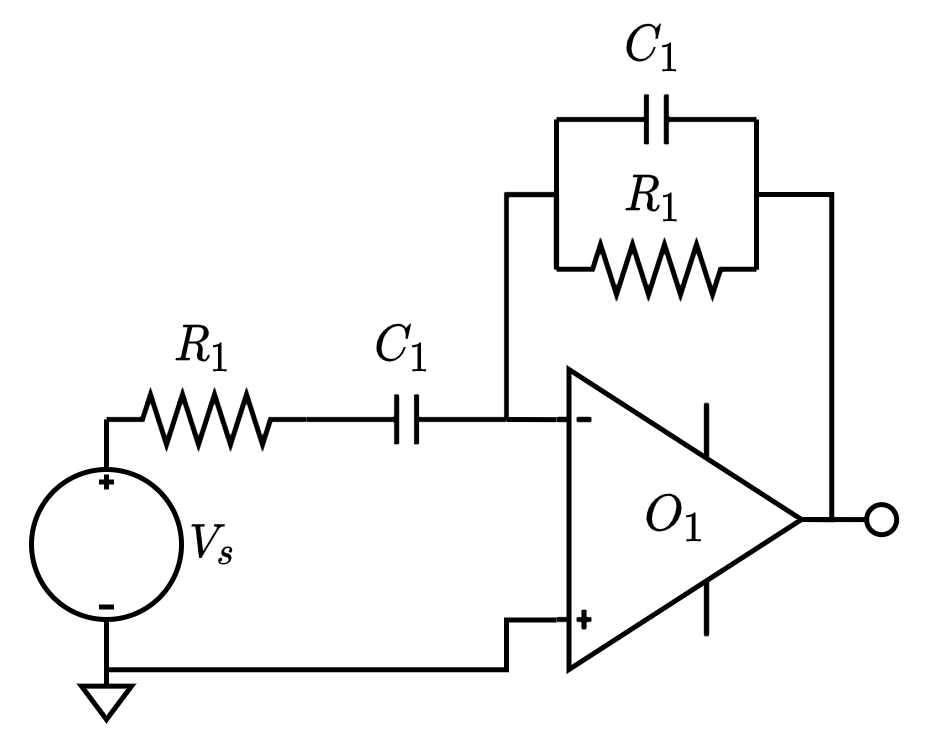

Suppose we want to know what values for the capacitors, we need to choose, to achieve poles at $p_1 =-1000\;\textrm{rad}/s$ and $p_2 =-5000\;\textrm{rad}/s$.

ELAB.ec2sd(circuit,1,4)

Symbolic analysis successful (0.396128 sec).
Symbolic transfer function calculated successfully (4.039197e-01 sec).


$$ans = \frac{v_{4}}{v_{1}}=-\frac{C_{1}\,R_{2}\,s}{\left(C_{1}\,R_{1}\,s+1\right)\,\left(C_{2}\,R_{2}\,s+1\right)}$$

From this transfer function, it is immediately apparent, that if $R_1 =R_2 =20k\Omega$, then $C_1 =1/1000R_1 =0\ldotp 05\mu F$ and $C_2 =1/5000=0\ldotp 01\mu F$.